%% limitations of sparsity w.r.t. a basis
close all
clear
clc

clc
M = 32; % signal dimension
N = 2*M;% number of atoms in the expansion

C = nan(M, M); % matrix containing the standard basis (a kronecker delta in each column)
DCT = nan(M, M); % matrix containing the DCT basis (a DCT function in each column)

%% generate the 1D-DCT basis
disp('generating 1-D DCT basis')

generating 1-D DCT basis


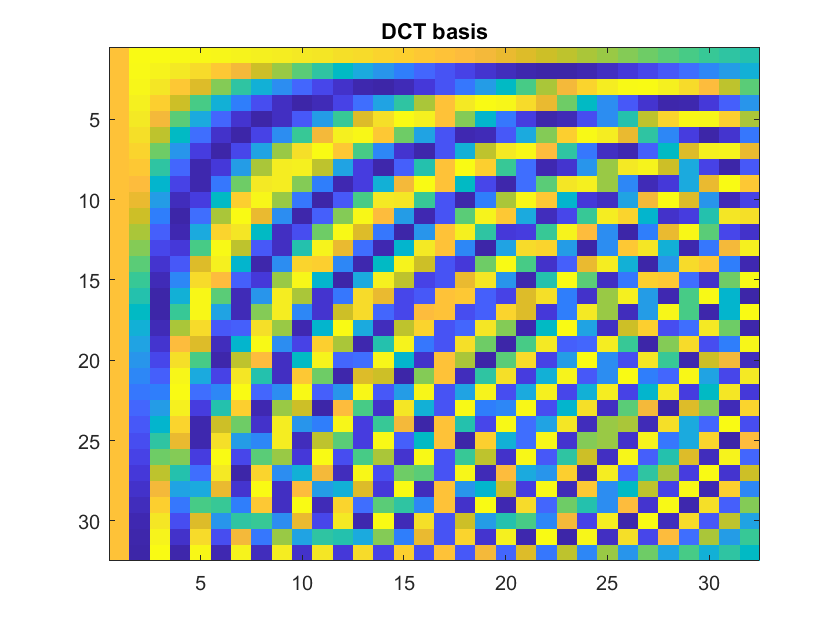

cnt = 1;
for ii = 1 : M
    a = zeros(1, M);
    a(ii) = 1;
    DCT(:, cnt) = idct(a)';
    cnt = cnt + 1;
end
figure(3), imagesc(DCT), title('DCT basis');


%% generate Standard orthonormal basis

disp('generating 1-D standard basis')

generating 1-D standard basis


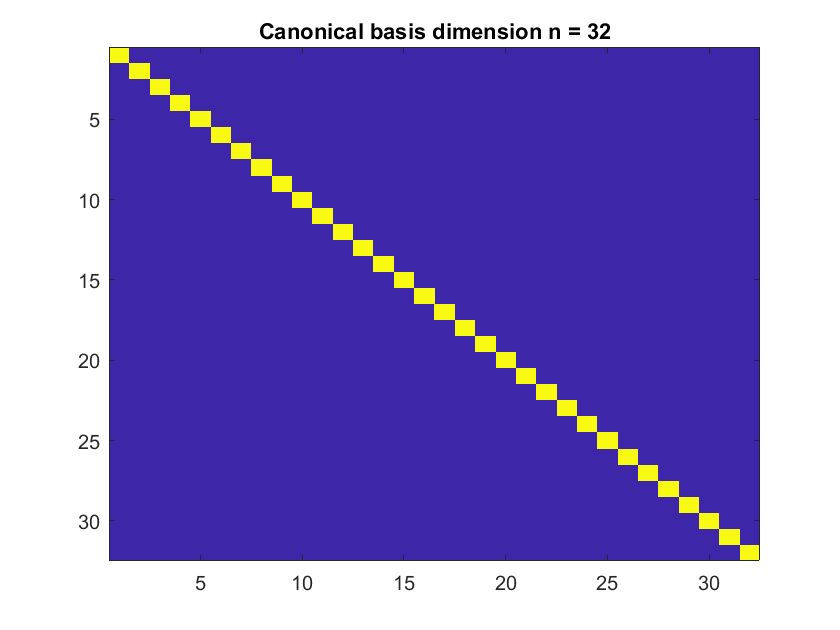

cnt = 1;
for ii = 1 : M
    a = zeros(1, M);
    a(ii) = 1;
    C(:, cnt) = a;
    cnt = cnt + 1;
end
figure(2), imagesc(C), title(['Canonical basis dimension n = ', num2str(M)]);

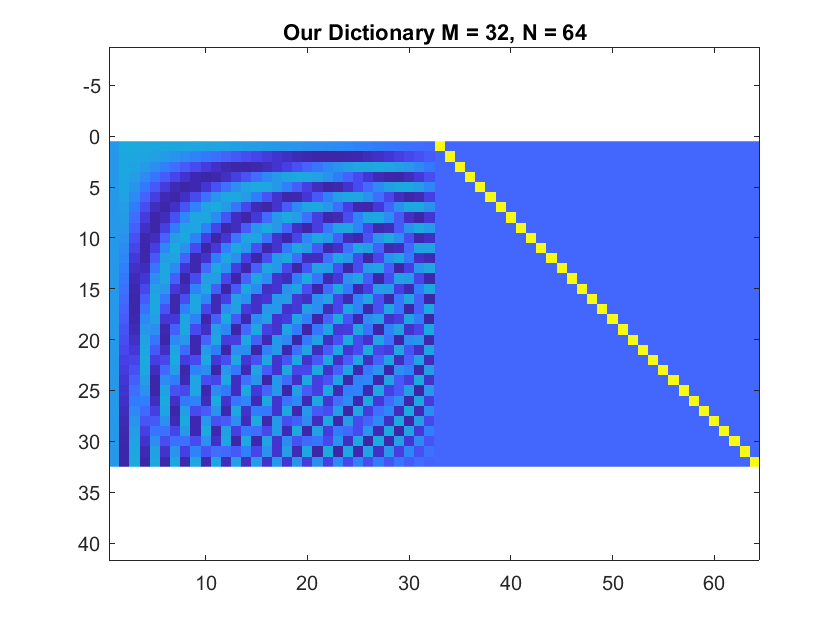


%% define the dictionary D = [DCT, C];
D = [DCT, C];
figure(3), imagesc(D), title(['Our Dictionary M = ', num2str(M), ', N = ', num2str(N)]);
axis equal

%% generate signals that are sparse w.r.t. [C, D], i.e. add a spike to the sum of few DCT atoms
% add a spike to s that is sparse w.r.t. D, bear in mind that the spike is to be considered a signal to be reconstructed,
% rather than noise


L = 5;
sigma_noise = 0.2;

% generate a signal that is sparse w.r.t. D

% randomly define the sparse representation w.r.t. [DCT,C]
% L - 1 nonzero coeff w.r.t DCT, 1 nonzero coeff w.r.t C (spike)
% DCT coeffs
values = 1./exprnd(0.2, 1, L-1);
indexes = randsample(M, L-1);
x0 = zeros(N, 1);
x0(indexes) = values;
% C coeff
spikeLocation = randsample(M:N, 1);
x0(spikeLocation) = 100;

% synthetize the corresponding signal in the signal domain
s0 = D * x0;

% add noise
s = s0 + random('normal', 0, sigma_noise, size(s0)); 

%% SPARSE CODING (ANALYSIS): compute the representation through MP

% initialization
x_MP = zeros(N,1);

% initialize the residual, namely the components of the signals that can not be represented (here the signal at the very beginning)
r = s;

l = 1;
% initialize the norm of the resiudal (components not represented by the coefficients)
%resNorm(l)
resNorm(l) = norm(r, 2);

MINIMUM_RES_NORM = 0.1;

%% MP Starts
% MP loop starts.
% stoppint criteria: continue until the sparsity of the representation reaches L 
%                    or as long as resNorm(l) is above a minimum value
%                    or as long as a maxium number of iterations have been reached

while (l <= L) && (resNorm(l) > MINIMUM_RES_NORM)%enter loop condition
    
    
    %% SWEEP STEP: look for the column of D that matches at best noisySignal
    % compute the residual w.r.t. each column of D
    for j = 1 : N
        % this corresponds to solving e(j) = min( || dj zj - s ||),
        % which is obtained by setting zj = dj' r / || dj ||^2 (analytically defined)
        % there is no need to divide by || dj ||^2 since columns are nomalized
        e(j) = resNorm(l)^2 - (r' * D(:,j))^2;
    end
    
    % find the column of D that matches at best r, i.e. jStar = argmin(e(j))
   [~,jStar] = min(e);
    
    %% UPDATE the support set the jStar coefficient by *summing* the new component dj' r^(i) / || dj ||^2
    x_MP(jStar) = x_MP(jStar) + r'*D(:,jStar);
    
    % remove the signal we have so far represented in coeff_MP (update the residual)
    r =  s - D * x_MP;% component that cannot be captured by the signal (the signal at the very beginning)
    
    l = l + 1;
    
    % update the residual norm
    resNorm(l) = norm(r, 2);
end

%% SYNTHESIS: reconstruct the signal

% invert the transformation to reconstruct the patch
s_hat_MP = D * x_MP;

% those part of the signal that have not been modeled by s_hat (i.e. the projection on the subspace of the L most
% involved coefficients) corresponds to the norm of the residual
resNorm_MP = resNorm(l)

resNorm_MP = 1.3960

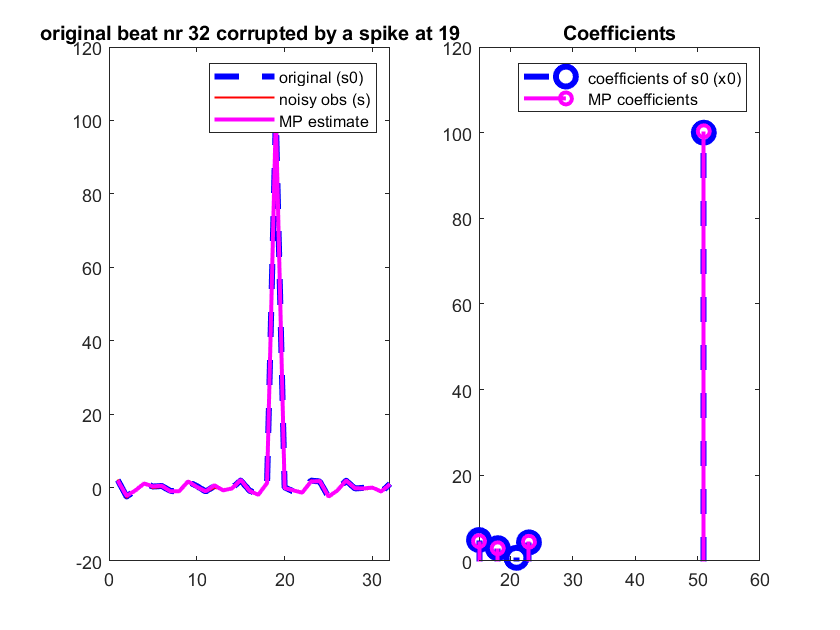


%% show the result
LN_WDT = 2;
MRK_SZ = 10;

figure(5)
subplot(1,2,1)
plot(s0, 'b--',  'LineWidth', LN_WDT + 1),
hold on
plot(s, 'r-',  'LineWidth', LN_WDT -1),

plot(s_hat_MP, 'm-', 'LineWidth', LN_WDT),
title(['original beat nr ', num2str(ii), ' corrupted by a spike at ', num2str(spikeLocation-M)]);
hold off
legend('original (s0)', 'noisy obs (s)', 'MP estimate')

subplot(1,2,2)
stem(find(x0 ~= 0), x0(x0~= 0), 'b--',  'LineWidth', LN_WDT + 1, 'MarkerSize', MRK_SZ),
hold on
stem(find(x_MP ~= 0), x_MP(x_MP ~= 0), 'm-', 'LineWidth', LN_WDT),
title('Coefficients')
hold off
legend('coefficients of s0 (x0)', 'MP coefficients')